## State space representation

clear all
%addpath("C:\Users\nicol\OneDrive\Documents\34746 - Robust & Fault Tolerent Control\Exercises\SA Tool\SaTool_3_0100\sa_tool_3_0100");
load('ECP_values.mat');
load('ECP502Data.mat');
% Physical system parameters
J_1 = ECP_values(1);            % Disk 1 inertia kgm^2
J_2 = ECP_values(2);            % Disk 2 inertia kgm^2
J_3 = ECP_values(3);            % Disk 3 inertia kgm^2
k_1 = ECP_values(4);            % Shaft 1-2 stiffness Nm/rad
k_2 = ECP_values(5);            % Shaft 2-3 stiffness Nm/rad
b_1 = mean(ECP_values([6 7]));  % Disk 1 damping and friction Nms/rad
b_2 = mean(ECP_values([8 9]));  % Disk 2 damping and friction Nms/rad
b_3 = mean(ECP_values([10 11]));% Disk 3 damping and friction Nms/rad
T_Cp = ECP_values(12);          % Disk 1 Coulomb friction in positive direction
T_Cm = ECP_values(13);          % Disk 1 Coulomb friction in negative direction
atan_scale = 100;               % Sign approximation factor
w_th = 0.75;                    % Threshold angular velocity rad/s

s = tf('s');
%syms s
A = [0 1 0 0 0 0
    -k_1/J_1 -b_1/J_1 k_1/J_1 0 0 0
    0 0 0 1 0 0
    k_1/J_2 0 -(k_1+k_2)/J_2 -b_2/J_2 k_2/J_2 0
    0 0 0 0 0 1
    0 0 k_2/J_3 0 -k_2/J_3 -b_3/J_3];
B = [0 0
    1/J_1 0
    0 0
    0 1/J_2
    0 0
    0 0];
B = B(:,1); 

C = [  1 0 0 0 0 0
       0 0 1 0 0 0
       0 0 0 0 1 0 ];
C = C(3,:);

D = [0 0
     0 0
     0 0];
D=0;


state = ss(A,B,C,D);
G0_tf = tf(state);


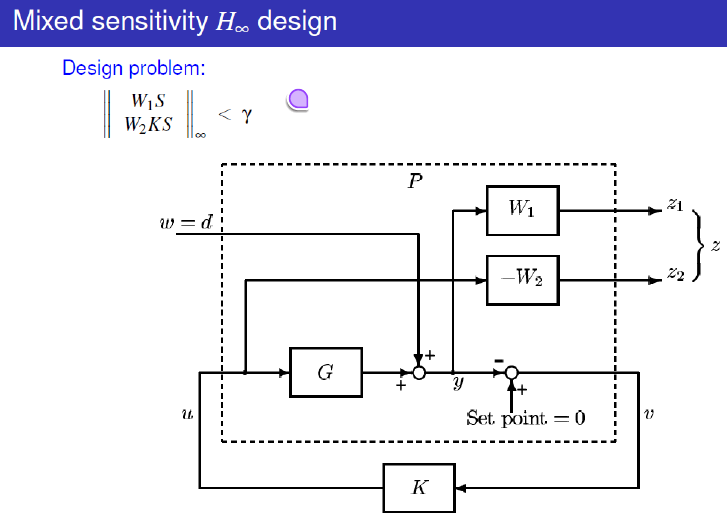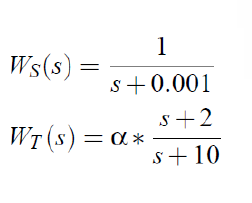

Ws = W1 

WT = W2

M_1 = 20;     % Stadig åben til fortolkning
A_1 = 0.0005;  % Looks OK
omega_star_1 = 2*pi/0.4;  % Bandwidth or not? 1, for bandwidth, 1/1.5*2*pi for Rad/s
M_2 = 10;     % Stadig åben til fortolkning
A_2 = 0.05;  % Looks OK
omega_star_2 = 2*pi/0.8;  % Bandwidth or not? 1, for bandwidth, 1/1.5*2*pi for Rad/s
scale=0.07;

W1 = scale*((s/M_1 + omega_star_1) / (s + omega_star_1*A_1))^2;
W2 = scale*((s + omega_star_2*A_2) / (s/M_2 + omega_star_2))^4;  % Same weight on KS for now
W3 = tf(0);


[K_Hinf, Cl, Gam, Info] = mixsyn(G0_tf, W1, W2, W3, 'METHOD', 'lmi', 'GMIN', 0, 'GMAX', 10);
Gam

Gam = 0.9885

size(K_Hinf)

State-space model with 1 outputs, 1 inputs, and 12 states.


[K_Hinf, Cl, Gam, Info] = mixsyn(G0_tf, W1, W2, W3, 'METHOD', 'lmi', 'GMIN', Gam*1.02, 'GMAX', Gam*1.05);
Cl = (G0_tf*K_Hinf)/(1+G0_tf*K_Hinf);
size(K_Hinf)

State-space model with 1 outputs, 1 inputs, and 12 states.


Gam

Gam = 0.9928

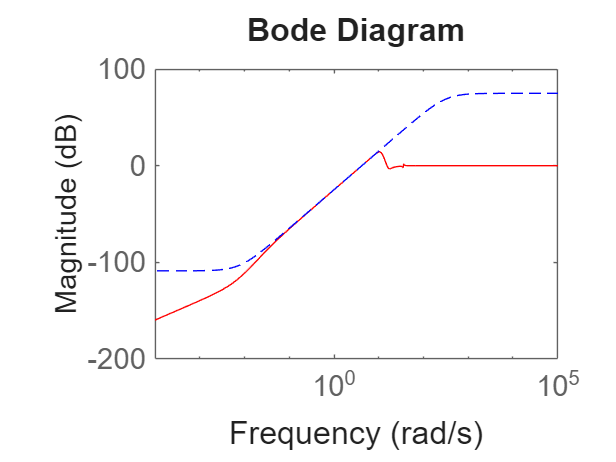

S_tf = feedback(1,G0_tf*tf(K_Hinf));


% Validation 

figure;
bodemag(S_tf,'r',Gam/(W1),'b--');

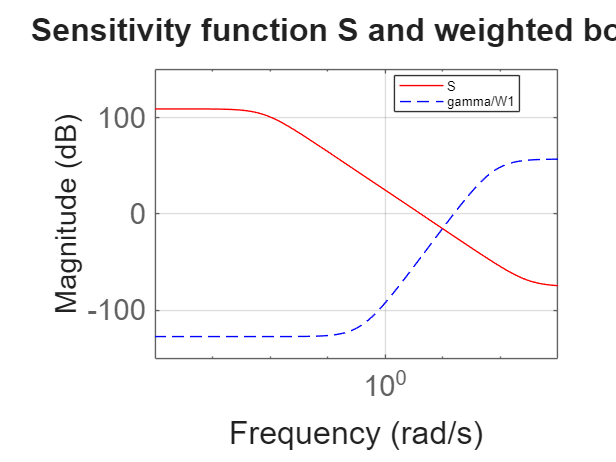

bodemag((W1),'r',(W2),'b--');
legend('S', 'gamma/W1','Location', 'best');
title('Sensitivity function S and weighted bound');
grid on;

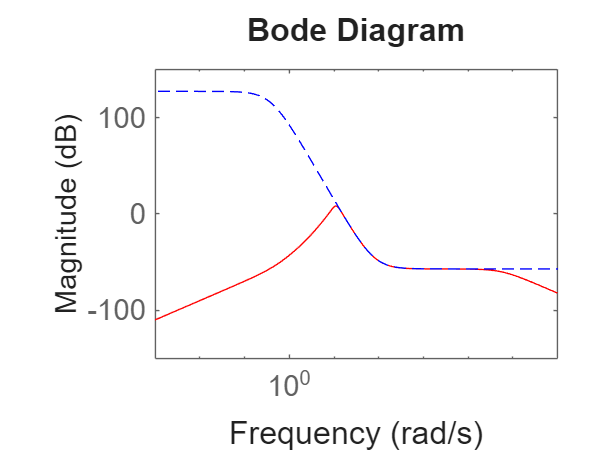

%saveas(gcf, 'figures/p1.png');
figure;
bodemag(K_Hinf*S_tf,'r',Gam/(W2),'b--');

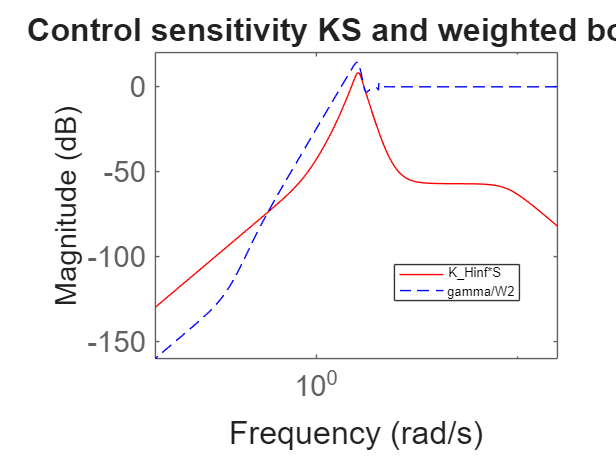

bodemag(K_Hinf*S_tf,'r',(S_tf),'b--');
legend('K_Hinf*S', 'gamma/W2','Location', 'best');
title('Control sensitivity KS and weighted bound');

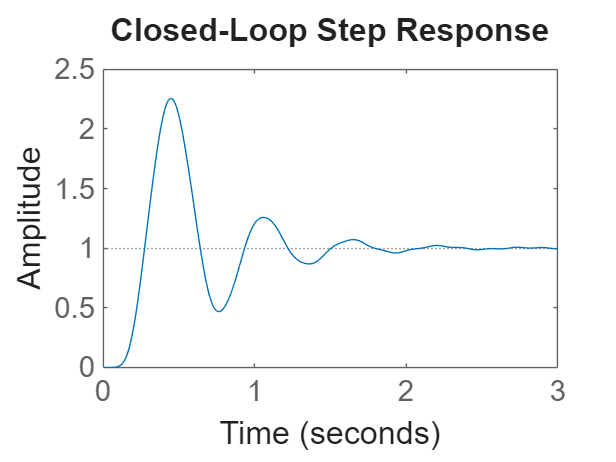

%saveas(gcf, 'figures/p2.png');

% Analyze
figure;
step(Cl)
title('Closed-Loop Step Response');

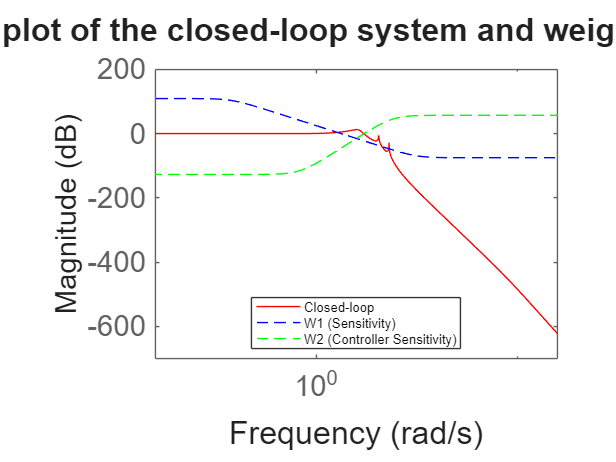




% Plot the closed-loop system
figure;
hold on;
bodemag(Cl, 'r'); 
bodemag(W1, 'b--');
bodemag(W2, 'g--');
legend('Closed-loop', 'W1 (Sensitivity)', 'W2 (Controller Sensitivity)', 'Location', 'best');
title('Bode plot of the closed-loop system and weight functions');

Question 10

% Reduce the controller order

order_desired = 8;  % Try 6th order
%K_reduced = reduce(K_Hinf, order_desired);
size(K_Hinf)

State-space model with 1 outputs, 1 inputs, and 12 states.


K_reduced = hankelmr(K_Hinf, order_desired);
size(K_reduced)

State-space model with 1 outputs, 1 inputs, and 8 states.


Cl_reduced = feedback(G0_tf, K_reduced);
size(G0_tf)

Transfer function with 1 outputs and 1 inputs.


eig(Cl_reduced)

ans =   -0.1192 +64.6886i
  -0.1192 -64.6886i
  -0.3305 +35.8166i
  -0.3305 -35.8166i
  -0.2443 +35.6831i
  -0.2443 -35.6831i
  -6.6117 +10.8944i
  -6.6117 -10.8944i
  -2.2697 +10.8424i
  -2.2697 -10.8424i


% Check poles
poles_Cl_reduced = pole(Cl_reduced);


% Poles and zeros of full controller
poles_full = pole(K_Hinf);
zeros_full = zero(K_Hinf)

zeros_full =   -0.1211 +64.6931i
  -0.1211 -64.6931i
 -97.6706 + 0.0000i
 -75.1544 +12.6924i
 -75.1544 -12.6924i
 -67.6790 + 0.0000i
  -0.3083 +35.7447i
  -0.3083 -35.7447i
  -2.9992 + 0.0000i
  -0.5503 + 0.0000i



% Poles and zeros of reduced controller
poles_reduced = pole(K_reduced);
zeros_reduced = zero(K_reduced)

zeros_reduced =  -34.8592 +54.8941i
 -34.8592 -54.8941i
  -0.2696 +35.7307i
  -0.2696 -35.7307i
  -3.1018 + 0.0000i
  -0.5467 + 0.0000i
  -0.0301 + 0.0000i


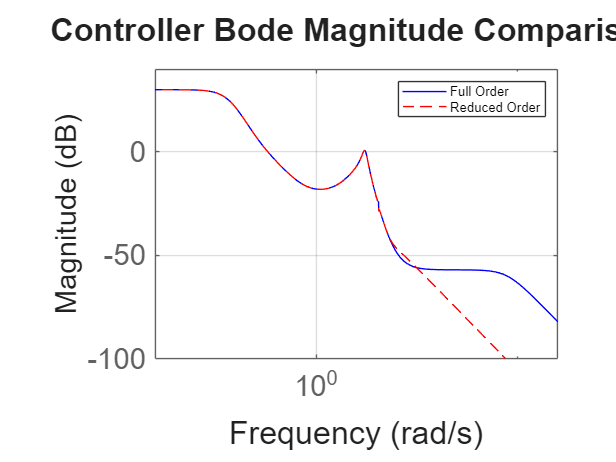



figure;
bodemag(K_Hinf, 'b', K_reduced, 'r--');
legend('Full Order', 'Reduced Order');
title('Controller Bode Magnitude Comparison');
grid on;

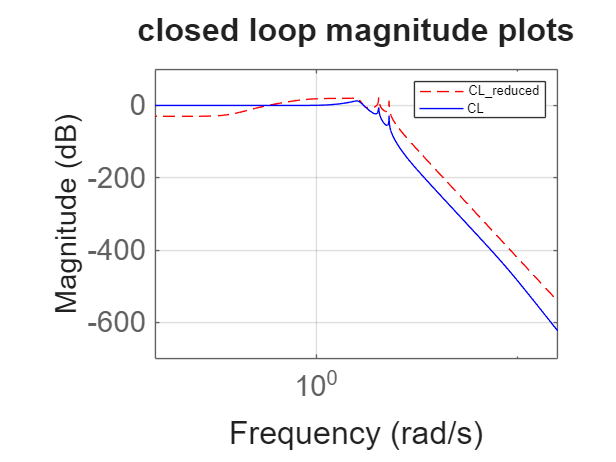

figure; 
bodemag(Cl_reduced,'r--',Cl,'b')
legend('CL_reduced','CL');
title('closed loop magnitude plots');
grid on; 

Question 11

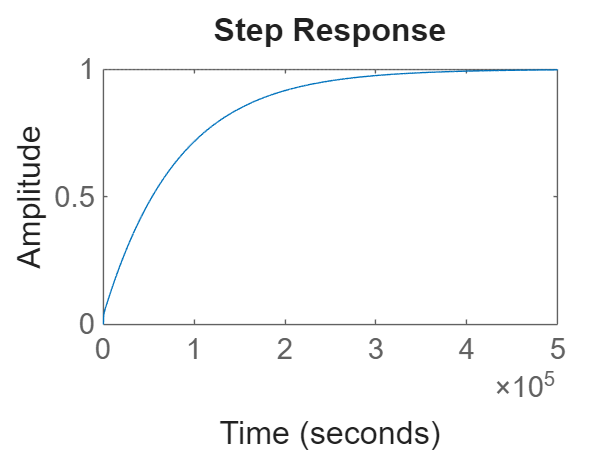


% Large gamma bounds, no minimization – "h2-like" behavior
[K_H2, CL_H2, gamma_H2, info_H2] = mixsyn(G0_tf, W1, W2, 1e6);
%Compare closed loop transfer functions
CL_Hinf = feedback(G0_tf * K_Hinf, 1);
CL_H2 = feedback(G0_tf * K_H2, 1);

step(CL_H2);

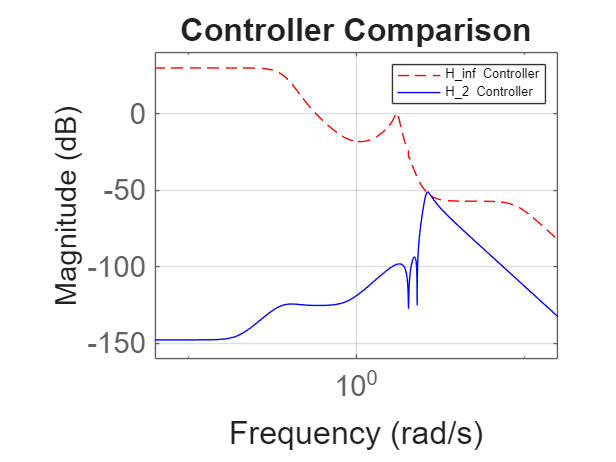


% Compare controllers 
figure;
bodemag(K_Hinf, 'r--', K_H2, 'b');
legend('H_inf Controller', 'H_2 Controller');
title('Controller Comparison');
grid on;

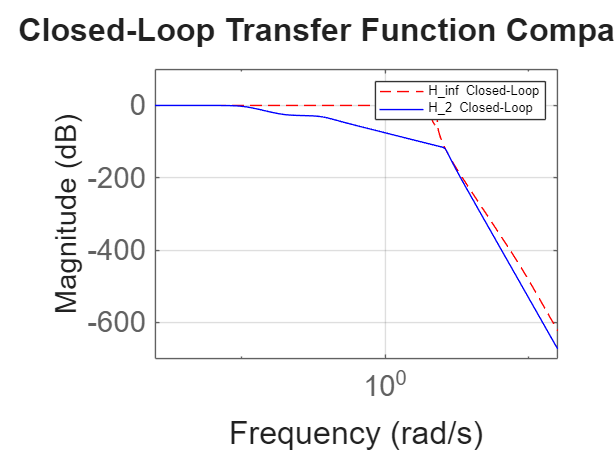




figure;
bodemag(CL_Hinf, 'r--', CL_H2, 'b');
legend('H_inf Closed-Loop', 'H_2 Closed-Loop');
title('Closed-Loop Transfer Function Comparison');
grid on;

Question 12

% Export controller
% K = ss(K_reduced);  % or K_Hinf if not reduced
x_0 = [0;0;0;0;0;0];            % Initial conditions
T_s = 0.004;                    % Sampling period
simTime = 45;                   % Simulation duration in seconds
d = zeros(simTime/T_s,0);
t = 0:T_s:simTime;
d_in = [t d];

Question 13

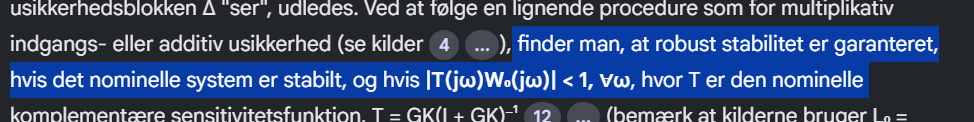

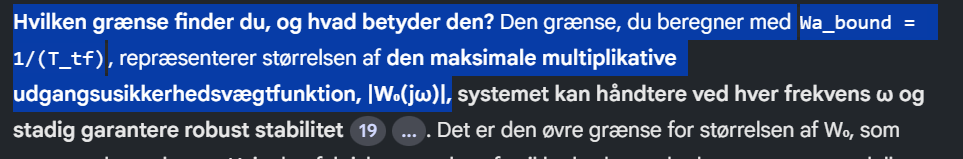

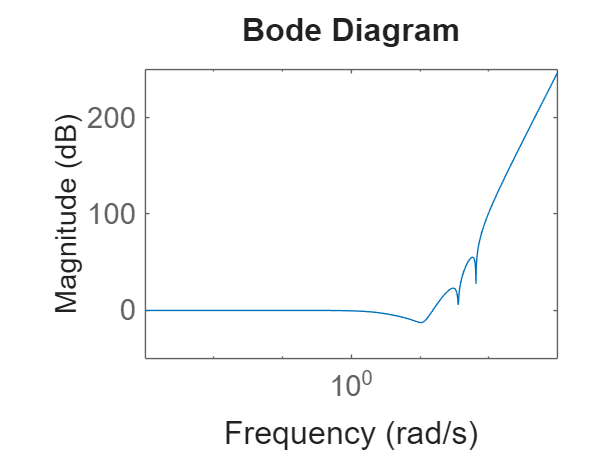

%Wa_upper = 1/abs(K_reduced*(eye(size(G0_tf))+G0_tf*K_reduced))    L14
figure;
T_tf = (G0_tf*K_reduced)/(1+G0_tf*K_reduced);
%T_tf = feedback(G0_tf*K_reduced,1)
Wa_upper = 1/(T_tf);
Wa_tf = ss2tf(Wa_upper.A,Wa_upper.B,Wa_upper.C,Wa_upper.D);
bodemag(Wa_upper)

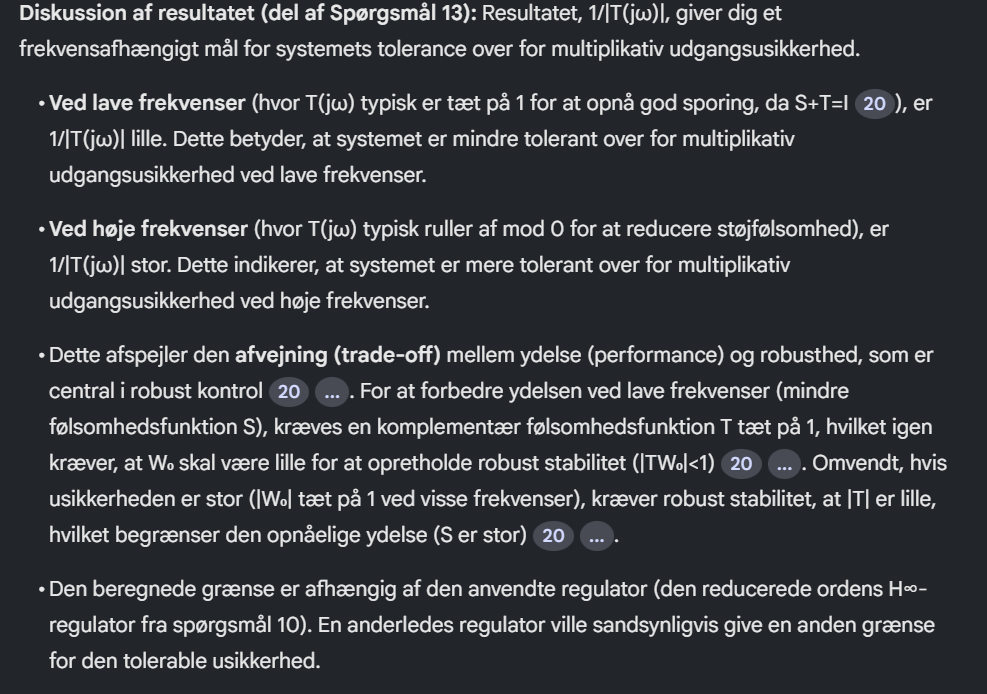 - crazy ai svar (good) 

% 
% % T: Complementary sensitivity function using reduced-order H_inf controller
% T_red = feedback(G0_tf * K_reduced, 1);
% 
% % Compute maximum gain of T (peak of magnitude)
% [mag_T, freq_T] = norm(T_red, inf);
% 
% % Max multiplicative uncertainty that can be tolerated
% max_uncertainty = 1 / mag_T;
% 
% fprintf('Max allowable multiplicative uncertainty at the output: %.4f\n', max_uncertainty);
% 
% % Plot T and compare with 1/W_Delta
% figure;
% bodemag(T_red, 'b', 'LineWidth', 1.5);
% hold on;
% bodemag(1/mag_T, 'r--', 'LineWidth', 1.5);
% legend('|T|', '1 / ||T||_∞ bound');
% title('Complementary Sensitivity and Robust Stability Bound');
% grid on;

Question 14

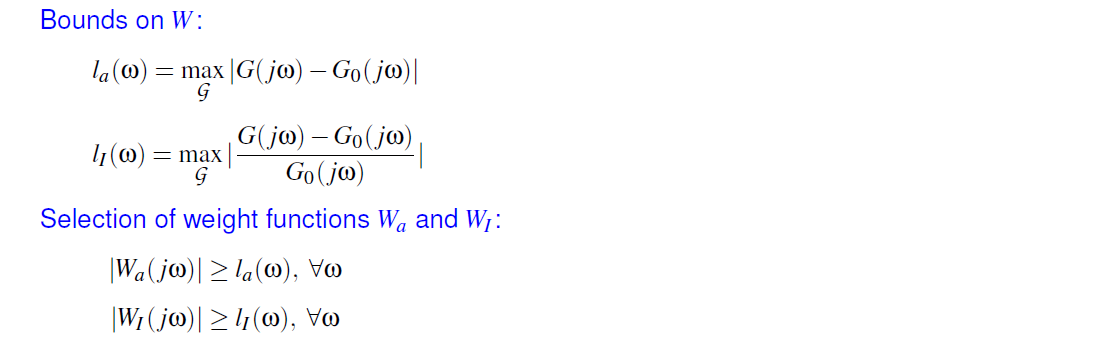

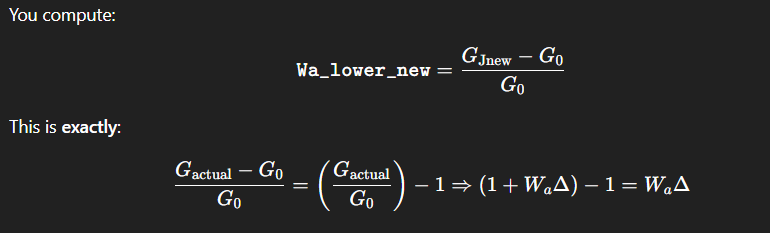 = derivation betweeen actual and norminal system. adn then normalized. 

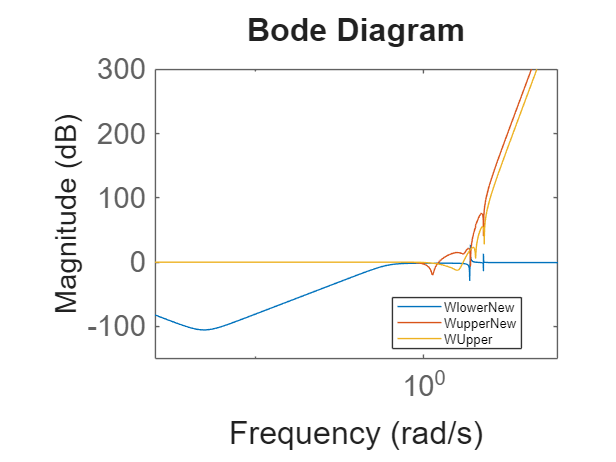

J_1 = 0.0325;
%syms s
A = [0 1 0 0 0 0
    -k_1/J_1 -b_1/J_1 k_1/J_1 0 0 0
    0 0 0 1 0 0
    k_1/J_2 0 -(k_1+k_2)/J_2 -b_2/J_2 k_2/J_2 0
    0 0 0 0 0 1
    0 0 k_2/J_3 0 -k_2/J_3 -b_3/J_3];
B = [0 0
    1/J_1 0
    0 0
    0 1/J_2
    0 0
    0 0];
B = B(:,1); 

C = [  1 0 0 0 0 0
       0 0 1 0 0 0
       0 0 0 0 1 0 ];
C = C(3,:);

D = [0 0
     0 0
     0 0];
D=0;

state_Jnew = ss(A,B,C,D);
G_Jnew = tf(state_Jnew);
T_tf_new = (G_Jnew*K_reduced)/(1+G_Jnew*K_reduced);
Wa_upper_new = 1/(T_tf_new);
Wa_lower_new = (G_Jnew-G0_tf)/(G0_tf);

figure
bodemag(Wa_lower_new,Wa_upper_new,Wa_upper)
legend('WlowerNew', 'WupperNew', 'WUpper', 'Location', 'best');

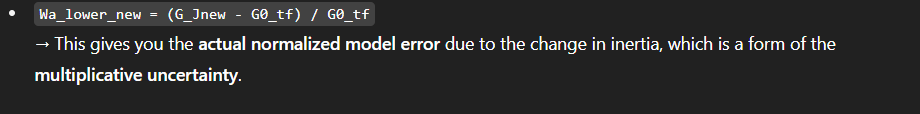

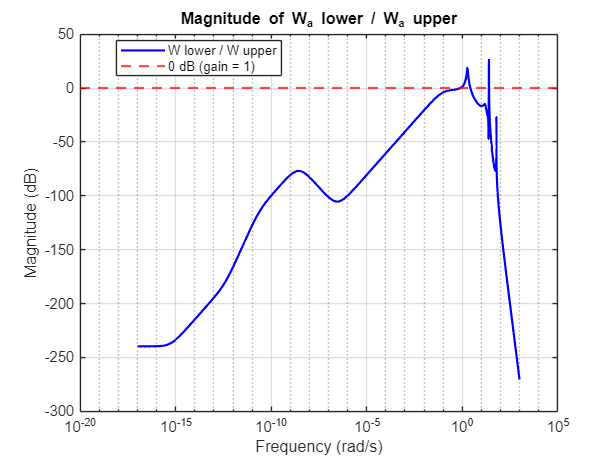

figure;
[mag, phase, w] = bode(Wa_lower_new / Wa_upper_new);
mag_dB = 20*log10(squeeze(mag));

semilogx(w, mag_dB, 'b', 'LineWidth', 1.5); % Plot magnitude in dB
hold on;
yline(0, 'r--', 'LineWidth', 1.5);          % Add horizontal line at 0 dB
grid on;
xlabel('Frequency (rad/s)');
ylabel('Magnitude (dB)');
title('Magnitude of W_a lower / W_a upper');
legend('W lower / W upper', '0 dB (gain = 1)', 'Location', 'best');

from chad: 

% % Reuse original A, B, C, D
% A_nom = A;
% A_new = A;
% J1_nom = 0.0025;
% J1_new = 0.0325;
% 
% % Replace the relevant A matrix entries for J1 in perturbed model
% A_new(2,:) = [-k_1/J1_new -b_1/J1_new k_1/J1_new 0 0 0];
% B_new = [0; 1/J1_new; 0; 0; 0; 0];
% 
% % Create systems
% G0 = ss(A_nom, B, C, D);
% G_new = ss(A_new, B_new, C, D);
% 
% % Compute transfer functions
% G0_tf = tf(G0);
% Gnew_tf = tf(G_new);
% 
% % Frequency range
% omega = logspace(-1, 2, 500);
% [mag_G0, ~] = bode(G0_tf, omega);
% [mag_Gnew, ~] = bode(Gnew_tf, omega);
% 
% % Compute multiplicative uncertainty (element-wise)
% mag_G0 = squeeze(mag_G0);
% mag_Gnew = squeeze(mag_Gnew);
% WI = abs((mag_Gnew - mag_G0) ./ mag_G0);
% 
% % Plot result
% figure;
% semilogx(omega, WI, 'b', 'LineWidth', 1.5);
% xlabel('Frequency [rad/s]');
% ylabel('|Δ(jω)|');
% title('Lower bound for uncertainty weight W_I');
% grid on;
% 
% % Compare to previous max allowed uncertainty
% yline(max_uncertainty, 'r--', 'LineWidth', 1.5);
% legend('|Δ(jω)| from J1 change', 'Max allowed from Q13');
% 

Question 15

%figure
%bodemag(WI,Wa_upper_new,Wa_lower_new)
%legend("'test",'upper','lower')
s = tf('s');
M_1 = 20;     % Stadig åben til fortolkning
A_1 = 0.0005;  % Looks OK
omega_star_1 = 2*pi/0.4;  % Bandwidth or not? 1, for bandwidth, 1/1.5*2*pi for Rad/s
M_2 = 10;     % Stadig åben til fortolkning
A_2 = 0.05;  % Looks OK
omega_star_2 = 2*pi/0.8;  % Bandwidth or not? 1, for bandwidth, 1/1.5*2*pi for Rad/s
scale=0.04;

W1 = scale*((s/M_1 + omega_star_1) / (s + omega_star_1*A_1))^2;
W2 = scale*((s + omega_star_2*A_2) / (s/M_2 + omega_star_2))^4;  % Same weight on KS for now
WI= scale*(0.833*s/(s+0.89)); %this is our W3

[K_Hinf, Cl, Gam, Info] = mixsyn(G_Jnew, W1, W2, WI, 'METHOD', 'lmi', 'GMIN', 0, 'GMAX', 10);

Gam

Gam = 0.9298

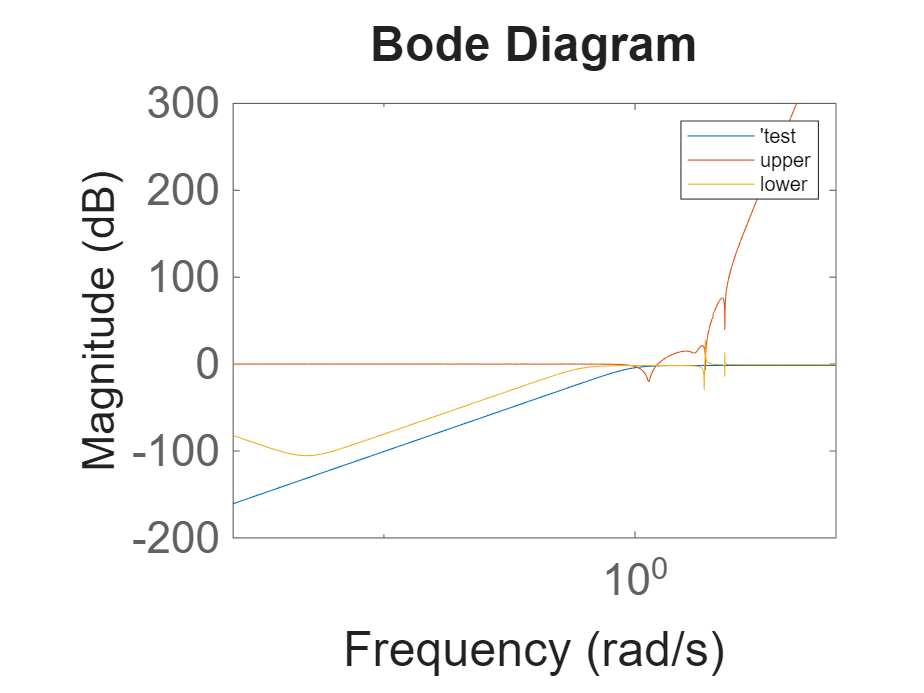


s = tf('s');

% Weight W1 (Sensitivity) - tracking requirement
M = 2; A = 0.001; omega_star = 1;
W1 = (s/M + omega_star)/(s + omega_star*A);

% Weight W2 (Control sensitivity) - limits control action
% High-pass filter, scaled to reduce bandwidth
W2 = (s + 0.5)/(0.05*s + 0.001);  % Tuned to limit fast response

% Weight W3 (Complementary sensitivity) - model uncertainty
W3 = (0.833*s)/(s + 0.089);

% Scale W1 and W2 to push gamma below 1
W1 = W1 / 1.1;
W2 = W2 / 1.1;

% Plant (SISO top disk angle)
G = ss(A,B,C,D);  % Already only top disk used

Error using ss (line 370)
The "A" and "B" matrices must have the same number of rows.


% H-infinity controller design
[K_Hinf_robust, CL_robust, gamma_robust, info_robust] = mixsyn(G, W1, W2, W3, ...
    'GMIN', 0.9, 'GMAX', 1.5, 'METHOD', 'lmi');

% Bode plots of closed-loop sensitivity functions
L = G*K_Hinf_robust;
S = feedback(1, L);
T = feedback(L, 1);
KS = K_Hinf_robust*S;

figure;
bodemag(S, 'r', 1/W1, 'b--'); grid on;
legend('Sensitivity S', '1/W1'); title('Sensitivity Function');

figure;
bodemag(KS, 'r', 1/W2, 'b--'); grid on;
legend('Control Sensitivity KS', '1/W2'); title('Control Sensitivity Function');

figure;
bodemag(T, 'r', 1/W3, 'b--'); grid on;
legend('Complementary Sensitivity T', '1/W3'); title('Model Uncertainty Handling');

% Step response analysis
figure;
step(feedback(G*K_Hinf_robust,1)); grid on;
title('Closed-loop Step Response');

% Display gamma value
disp(['Achieved gamma: ', num2str(gamma_robust)]);



Question 16



% Use this in MATLAB to launch and simulate
open_system('your_simulink_model');
 
% Set J1 in the base workspace for the model to use
J1 = 0.0025;
sim('your_simulink_model');

J1 = 0.0325;
sim('your_simulink_model');



% Plot both responses for comparison:
figure;
plot(t_nominal, y_nominal, 'b', 'LineWidth', 1.5); hold on;
plot(t_heavy, y_heavy, 'r--', 'LineWidth', 1.5);
legend('Nominal J1', 'Increased J1');
xlabel('Time (s)'); ylabel('Top Disk Angle (rad)');
title('Step Response Comparison');
grid on;







